# Opciones de salida

Al contrario de la entrada definida por el usuario (que iba del usuario al programa simple), ahora se tratará de las salidas (que van del programa simple al usuario).

Para que quede lo más claro posible el tema de entrada y salida de información, imaginemos una computadora y sus componentes. Una computadora dispone de teclado (medio por el que se ingresa información) y una pantalla (medio por el que se visualiza la inforación). Esto es lo que sucede aquí: una entrada funciona como un teclado y una salida funciona como una pantalla, en el caso de las computadoras.

La forma más sencilla de mostrar una salida es no escribir un punto y coma (`;`) al final de una variable.

clear
A = randi(10, 3)

A =      8     1     7
    10     9     8
     7    10     8


O si ya se tiene una variable creada, basta con escribir el nombre de esa variable.

A;

Como se puede notar, en ambos casos se despliega el nombre de la variable y lo que contiene.

Sin embargo, existen funciones que permiten controlar la salida de información.

## Función `disp`

La función despliegue (`disp`) se puede usar para desplegar los contenidos de una matriz sin imprimir el nombre de matriz.

disp(A)

     8     1     7
    10     9     8
     7    10     8



También se puede usar esta función para desplegar una cadena.

frase = "Ayer no me bañé"

frase = "Ayer no me bañé"

disp(frase)

Ayer no me bañé


**Recomendación:** Al igual que pasaba cuando revisamos las etiquetas para las gráficas, si se quiere incluir un apóstrofe dentro de la cadena habría que escribirlo dos veces. ¿Puedes entender el porque?

franquicia = "Mac Donald's";
disp(franquicia)

Mac Donald's


### Función `num2str`

En ocasiones nos interesará detallar la información de salida y luego imprimir esa misma información. Para este propósito podríamos hacer lo siguiente:

"Hola." + " Me llamo Isacc"

ans = "Hola. Me llamo Isacc"

Sin embargo, notemos que se muestran en líneas diferentes y también debemos usar 2 `disp`. Para evitar esto podemos utilizar la función `num2str` que convierte un double en string. Para ello creamos una matriz de string como sigue:

"n = " + 5

ans = "n = 5"

"n = " + num2str(5)

ans = "n = 5"

Si únicamente se escribiera el vector **A** sin utilizar la función `num2str`, simplemente se desplegaría la cadena más no los valores del vector. (Pruébalo por ti mismo).

## Función `fprintf`

La función `fprintf` (función impresión formateada) le da incluso mayor control sobre la salida de la que tiene con la función `disp`. Además de desplegar valores tanto texto como matriz, puede especificar el formato a usar al desplegar los valores, y puede especificar cuándo saltar a una nueva línea, entre muchas otras características.

**Nota:** Esta función es la mejor para salida: permite un control absoluto sobre la salida y es muy fácil.

La sintaxis es la siguiente:

Que no asuste esa sintaxis que ahora la explicamos. Lo que nos dice es que primero se ingresa una cadena y luego las variables (sin necesidad de tener que usar la función `num2str`).

Miremos el siguiente ejemplo:

clear; clc

nombre = input("Ingrese su nombre: ", "s");
edad = input("Ingrese su edad: ");
estatura = input("Ingrese su altura (m): ");

fprintf("Tu nombre es %5s, tienes %5i años y tu estatura es %5.3f m.", ...
    nombre, edad, estatura)

Tu nombre es Isacc, tienes    14 años y tu estatura es 1.210 m.

Hagamos algunas observaciones del ejemplo anterior:

- El marcador de posición (placeholder) (`%`) indica donde se insertará el valor de la variable.

- La letra `d` (double) que va seguida del marcador de posición indica el tipo de variable que se insertará.

- Luego de indicar qué tipo de variable se insertará sigue la cadena (el punto después de la `d` es un punto final, ¡debemos escribir apropiadamente, eh!).

### Tipo de dato

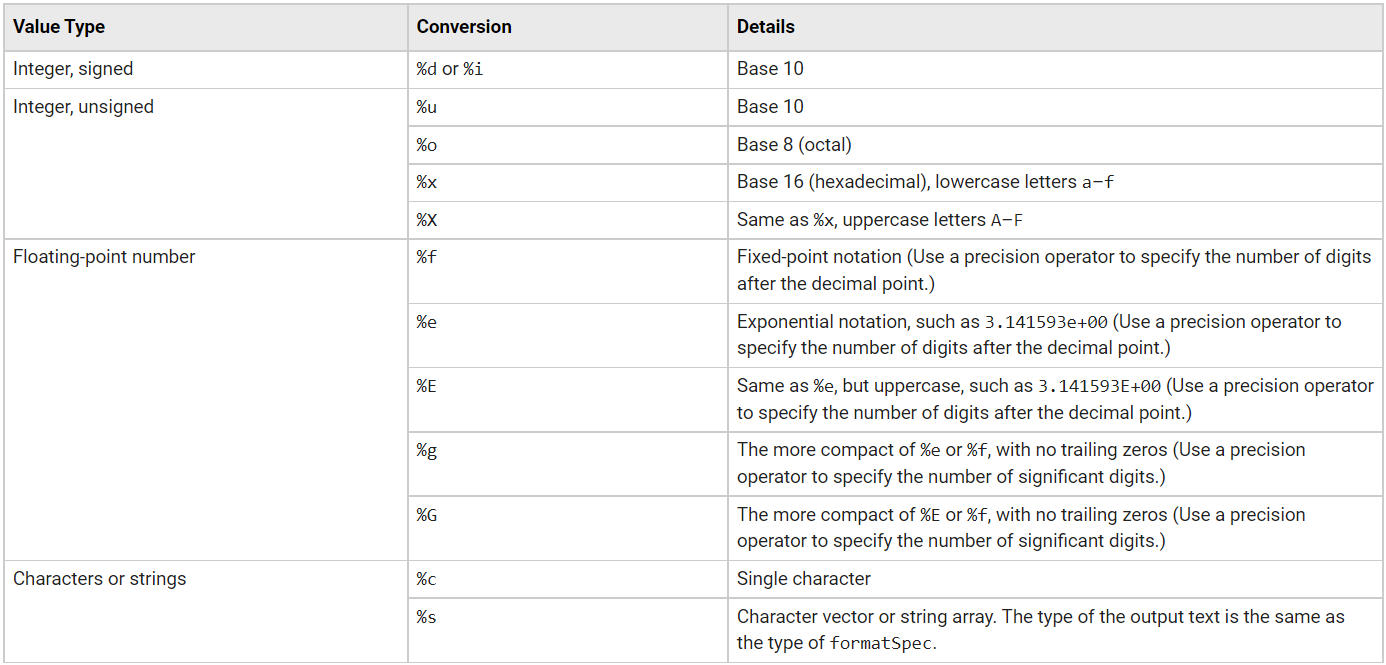

### Operadores para dar formato al texto

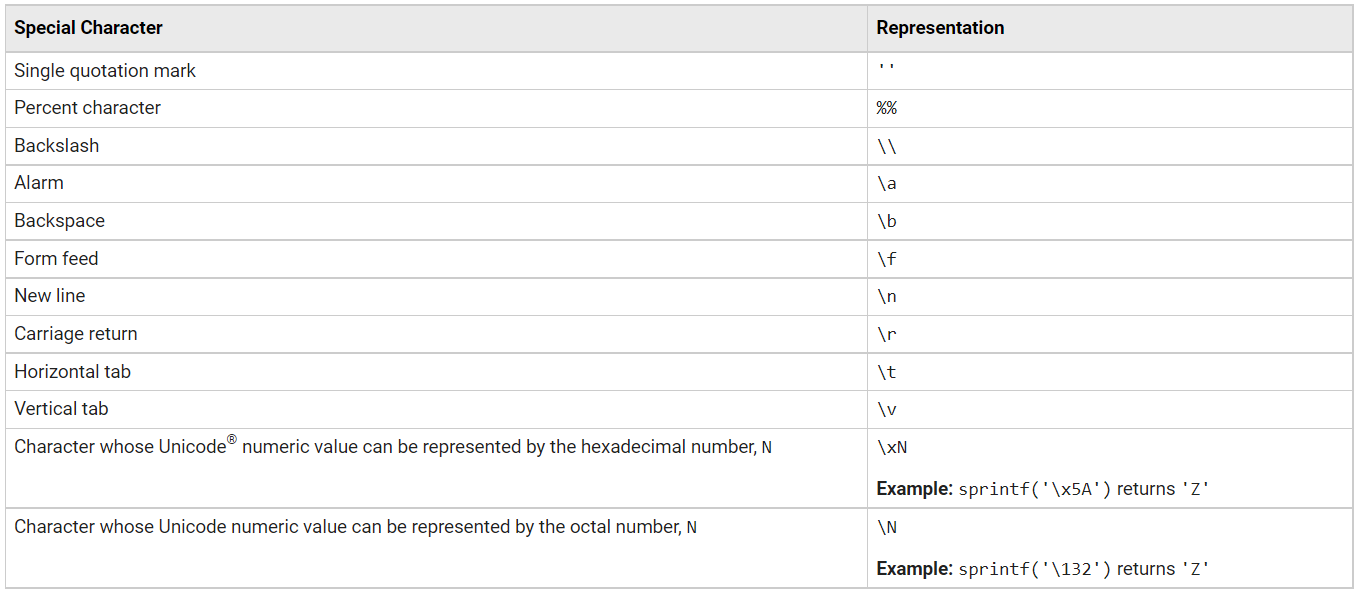

Veamos otro ejemplo:

clear
idx = 1:50

idx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


v = randi(10, size(idx))

v =      7     1     1     4     6     7     5     9     8    10     6     4     2     7     8     5     1     3     2     3     5     6     5     9     6    10     7    10     3     7     3     7     7     1     3     3     7     9     4     8     7     1     7     4    10     1     5     5     5     8


M = [idx; v]

M =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     7     1     1     4     6     7     5     9     8    10     6     4     2     7     8     5     1     3     2     3     5     6     5     9     6    10     7    10     3     7     3     7     7     1     3     3     7     9     4     8     7     1     7     4    10     1     5     5     5     8


fprintf("El índice %2i corresponde al número aleatorio %2i.\n", M)

El índice  1 corresponde al número aleatorio  7.
El índice  2 corresponde al número aleatorio  1.
El índice  3 corresponde al número aleatorio  1.
El índice  4 corresponde al número aleatorio  4.
El índice  5 corresponde al número aleatorio  6.
El índice  6 corresponde al número aleatorio  7.
El índice  7 corresponde al número aleatorio  5.
El índice  8 corresponde al número aleatorio  9.
El índice  9 corresponde al número aleatorio  8.
El índice 10 corresponde al número aleatorio 10.
El índice 11 corresponde al número aleatorio  6.
El índice 12 corresponde al número aleatorio  4.
El índice 13 corresponde al número aleatorio  2.
El índice 14 corresponde al número aleatorio  7.
El índice 15 corresponde al número aleatorio  8.
El índice 16 corresponde al número aleatorio  5.
El índice 17 corresponde al número aleatorio  1.
El índice 18 corresponde al número aleatorio  3.
El índice 19 corresponde al número aleatorio  2.
El índice 20 corresponde al número aleatorio  3.
El índice 21 corresp

Notemos varias cosas:

- El número de marcadores de posición dependerá del número de variables que queramos imprimir.

- La diagonal inversa (`\`) sirve para añadir algunos comandos de formato. En este caso, para insertar un salto de línea se utiliza `\n`. Algo a destacar es, lo que está inmediatamente antes e inmediatamente después de  `\n` es una cadena. (Pruebe a poner espacios antes y después del comando para ver qué sucede).

- Finalmente, el tipo de variable que se insertará es float (`f`) (básicamente decimales) y con el "punto + número" antes de `f` indico cuántos decimales deseo añadir. (Pruebe a añadir 2 o más decimales).

**Nota:** Es una buena práctica finalizar con un salto de línea cuando se trabajar con scripts .m porque todo lo que imprima se refleja en la ventana de comandos. (O pruebe a usar un `fprintf` sin salto de línea final y luego haga una operación básica como `1+1` y verá a que nos referimos).

Realicemos otro ejemplo:

% Su código va aquí :)

Analicemos el ejemplo:

- Por si hay dudas del porqué no había nada antes del punto, es porque MATLAB asigna `0` al valor antes o después del punto si no se especifica. En este caso hemos escrito un `8` que le da la orden a MATLAB de que deje 8 espacios antes del punto decimal (incluidos los números). (Pruebe a correr el mismo código pero sin el `8`).

- Luego, si se ingresa una matriz como variable a imprimir MATLAB tomará cada valor de la variable y lo irá imprimiendo uno por uno. En este caso es de suma importancia el salto de linea (`\n`) para que los resultados se vayan imprimiendo uno debajo de otro.(Pruebe a correr el mismo código pero sin el salto de línea y con una matriz 1:20).

Hagamos un último ejemplo:

% Su código va aquí :)

Entonces realicemos las observaciones:

- Cuando se tratan de matrices bidimensionales, MATLAB toma los valores por columna. Es decir, primero toma la primera columna, luego la segunda, etc.

- Si sólo estamos imprimiendo una variable ¿por qué hay dos marcadores de posición? Sencillo, para que MATLAB tome los valores más rápido. Es decir, MATLAB tomará el primer valor de la primera columna (`1`) y le dará un 4 espacios antes del punto con `0` decimales, luego tomará el siguiente valor de la columna (4) y le asignará 7 espacios antes del punto con `2` decimales, etc.

- En síntesis, en lugar de tomar los valores de 1 en 1, MATLAB irá tomando los valores de 2 en 2 (porque hay 2 marcadores de posición para 1 matriz) y les irá asignado el formato correspondiente.

Quizá este ejemplo haya sido un poco más complejo, pero si se entiende se logrará realizar impresiones muy elegantes controlando a detalle lo que se imprimirá.

Sin embargo, esto fue un breve resumen de lo más básico de esta función. Para mayor dominio y conocimiento se recomienda consultar la documentación. Esta función es muy compleja en cuanto a lo que puede hacer, pero una vez se acostumbre a ella verá lo útil que es.

**Nota:** Al igual que pasa con el pasaba con la impresión del apóstrofe en la función `disp` (y para esta función también aplica), algunos caracteres especiales requieren ser escritos dos veces para que aparezcan. Entre ellos están el símbolo `%` y `\`.

% Su código va aquí :)